# MPC

## modelo de 6 polso



% planta modelada con system Identification
xg = [5.671618964260603e+05];
yg = 1.0e+05 *[0.000010000000000 0.000582840996742 0.012844454912094 0.162297100468771 1.087898782652298 3.983829952470905 5.775054615523315];

G_posta = tf(xg, yg);

% matriz de estados continuo
% x' = A * x + B * u
% y  = C * x + D * u

sys = ss(G_posta);

% matriz de estados discreto
% x+1 = Ad * x + Bd * u
% y   = Cd * x + Dd * u

Tm = 0.030;

sysd = c2d(sys, Tm, 'zoh');


% matriz extendida
% xe = [x; u]
% xe+1 = Ae * xe + Be * du
% y    = Ce * xe + De * du

% Ae = [Ad B;
%       0  I]

Ae =[sysd.A         sysd.B;
    [0 0 0 0 0 0]   1];

% Be = [Bd;
%       1]

Be = [sysd.B;
       1];

% Ce = [Cd Dd]

Ce = [sysd.C sysd.D];

% De = Dd

De = sysd.D;



## Modelo ideal de la planta

% modelo discreto extendido

Tm  = 0.030;
tau = 0.100;

p = exp(-(Tm/tau))

p = 0.7408

e = 1 - p

e = 0.2592


A = [p e 0 0 0 0 0;
     0 p e 0 0 0 0;
     0 0 p e 0 0 0;
     0 0 0 p e 0 0;
     0 0 0 0 p e 0;
     0 0 0 0 0 p e;
     0 0 0 0 0 0 1];

B = [0;
     0;
     0;
     0;
     0;
     e;
     1;];

C = [1 0 0 0 0 0 0];

D = 0;


## matrices modelo de prediccion

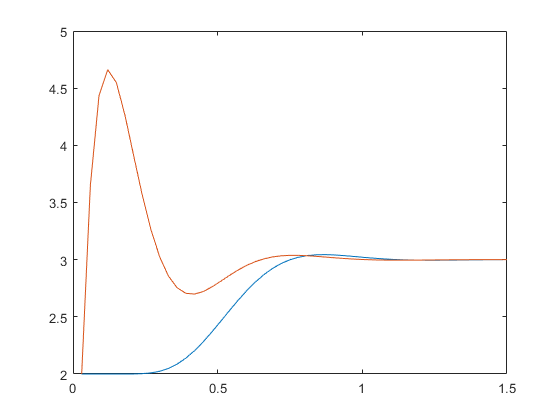

Np = 100;
Nc = 3;

[Phi_Phi Phi_F Phi_R Phi F] = mpcgain(A, B, C, Np, Nc);

x0 = 1;
referencia  = 4;

% x = [y  x5 x4 x3 x2 x1 u]
aux = [1; 1; 1; 1; 1; 1; 1] * x0;
x(:,1) = aux;

T = 1.5;
for i=2:T/Tm
    dU = inv(Phi_Phi + eye(Nc) * 0.3)*(Phi_R * referencia - Phi_F * aux);
    aux = A * aux + B * dU(1);
    x(:,i) = aux;
end

plot((Tm:Tm:T), x(1,:),(Tm:Tm:T), x(7,:))